clc;clear;
warning off
run("data/LabStartup.mlx");
run("data/quanser_aero_parameters.m");
run("data/quanser_aero_state_space.m");

Delta_1 = 0;
Delta_2 = 0;

s = tf('s');
G_unc = minreal(ss(A, B, C, D));
G_nom = G_unc.NominalValue;
G_vec = usample(G_unc, 100);

M = 2;          % S peak of no more than 6 db = 2 mag
a = 100;        % Rejects steady state disturbances by a factor of 100
wc = 5;         % Crossover frequency

[~, info] = ucover(G_vec, G_nom, [2, 2]);
WI = info.W1;
W_I_Pitch = WI(1,1);
W_I_Yaw = WI(2,2);

# Inverse

## 3.) Implement your final controller on the hardware (using Δ = 0 ) . Plot the response from your hardware implementation (angles and voltages). If you are seeing instability here, perhaps decrease 𝜔𝑐 and retry.

hf_pole = 100;  % high frequency pole

isproper(inv(G_unc))

ans = logical
   0


G_inv = 1/(s/hf_pole+1)^2*inv(G_unc);
isproper(G_inv)

ans = logical
   1


L_des = wc/s*eye(2);
K_inv = minreal(tf(L_des*G_inv));
K_inv = ss(K_inv);
K = K_inv;

## 4.) Run the hardware simulation for 5 uncertain samples and plot the performance. Note that the system may hit the hard stops / become unstable. If this occurs, choose a new sample and rerun.

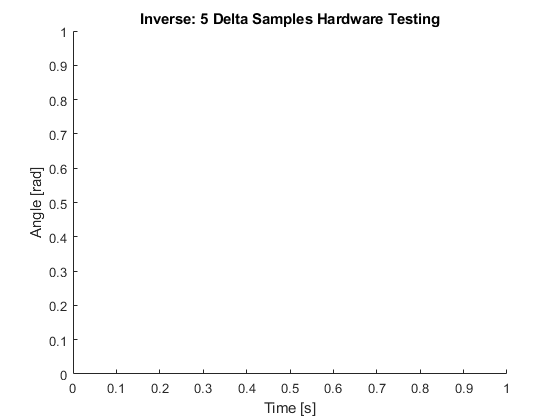

figure();
xlabel("Time [s]"); ylabel("Angle [rad]");
title("Inverse: 5 Delta Samples Hardware Testing");

Delta_1 = usample(D_1, 1);
Delta_2 = usample(D_2, 1);

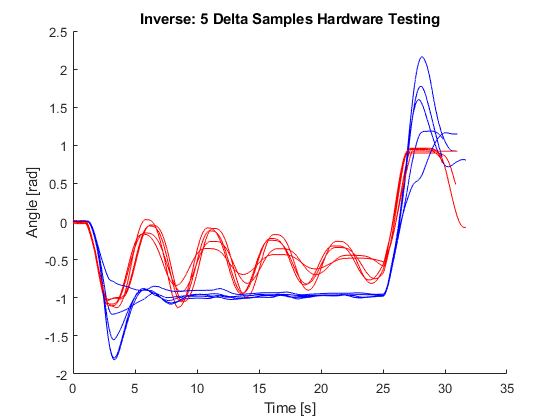

hold on;
plot(pitch_only.time, pitch_only.signals.values, 'r');
plot(yaw_only.time, yaw_only.signals.values, 'b');

# H2 Synthesis

## 3.) Implement your final controller on the hardware (using Δ = 0 ) . Plot the response from your hardware implementation (angles and voltages). If you are seeing instability here, perhaps decrease 𝜔𝑐 and retry.

hf_pole = 100;  % high frequency pole
Wu = tf([1], [18])*eye(2); % control usage limited to the maximum voltage
Wp = makeweight(a, wc, 1/M)/(s/hf_pole+1)*eye(2);

systemnames = 'G_nom Wp Wu';
inputvar = '[r{2};u{2}]';
outputvar = '[Wp;Wu;r-G_nom]';
input_to_G_nom = '[u]';
input_to_Wu = '[u]';
input_to_Wp = '[r-G_nom]';
cleanupsysic = 'yes';  %This drops all the useless variables from workspace
P = sysic;

[K2,CL2,GAM2,info] = h2syn(P, 2, 2);
K = minreal(K2);

## 4.) Run the hardware simulation for 5 uncertain samples and plot the performance. Note that the system may hit the hard stops / become unstable. If this occurs, choose a new sample and rerun.

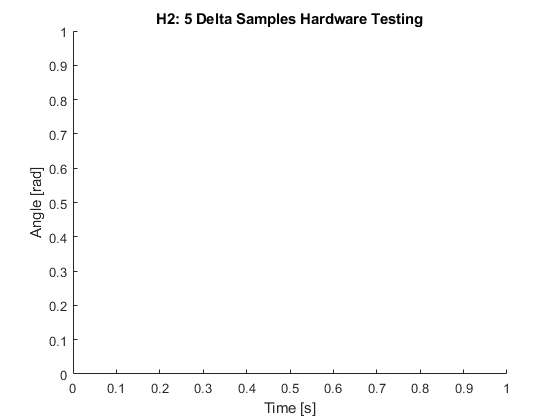

figure();
xlabel("Time [s]"); ylabel("Angle [rad]");
title("H2: 5 Delta Samples Hardware Testing");

Delta_1 = usample(D_1, 1);
Delta_2 = usample(D_2, 1);

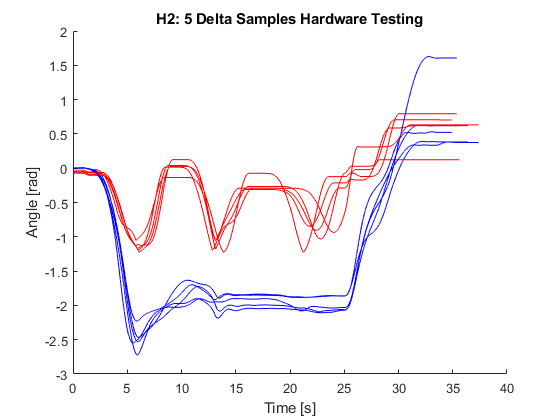

hold on;
plot(pitch_only.time, pitch_only.signals.values, 'r');
plot(yaw_only.time, yaw_only.signals.values, 'b');

# Hinf Synthesis

## 3.) Implement your final controller on the hardware (using Δ = 0 ) . Plot the response from your hardware implementation (angles and voltages). If you are seeing instability here, perhaps decrease 𝜔𝑐 and retry.

hf_pole = 100;  % high frequency pole
Wu = tf([1], [18])*eye(2); % control usage limited to the maximum voltage
Wp = makeweight(a, wc, 1/M)*eye(2);

systemnames = 'G_nom Wp Wu';
inputvar = '[r{2};u{2}]';
outputvar = '[Wp;Wu;r-G_nom]';
input_to_G_nom = '[u]';
input_to_Wu = '[u]';
input_to_Wp = '[r-G_nom]';
cleanupsysic = 'yes';  %This drops all the useless variables from workspace
P = sysic;

[Kinf,CLi,GAMi] = hinfsyn(P,2,2);
K = Kinf;

## 4.) Run the hardware simulation for 5 uncertain samples and plot the performance. Note that the system may hit the hard stops / become unstable. If this occurs, choose a new sample and rerun.

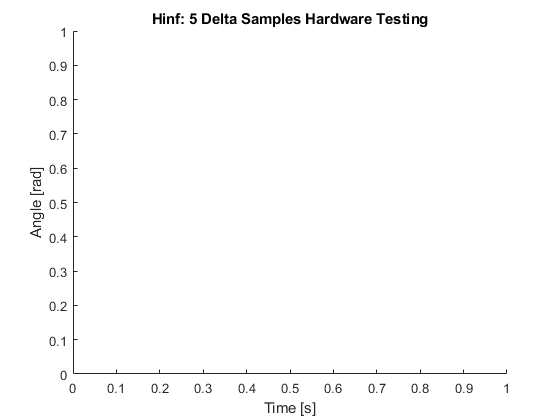

figure();
xlabel("Time [s]"); ylabel("Angle [rad]");
title("Hinf: 5 Delta Samples Hardware Testing");

Delta_1 = usample(D_1, 1);
Delta_2 = usample(D_2, 1);

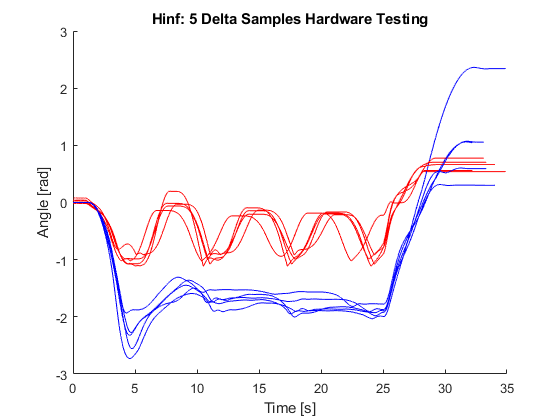

hold on;
plot(pitch_only.time, pitch_only.signals.values, 'r');
plot(yaw_only.time, yaw_only.signals.values, 'b');

# mu Synthesis

## 3.) Implement your final controller on the hardware (using Δ = 0 ) . Plot the response from your hardware implementation (angles and voltages). If you are seeing instability here, perhaps decrease 𝜔𝑐 and retry.

hf_pole = 100;  % high frequency pole
Wu = tf(1, 18)*eye(2); % control usage limited to the maximum voltage
Wp = makeweight(a, wc, 1/M)*eye(2);

systemnames = 'G_unc Wu Wp';
inputvar = '[r{2};u{2}]';
outputvar = '[Wp;Wu;r-G_unc]';
input_to_G_unc = '[u]';
input_to_Wu = '[u]';
input_to_Wp = '[r-G_unc]';
cleanupsysic = 'yes';  %This drops all the useless variables from workspace
P = sysic;

[Kmu, CL, mu_syn] = dksyn(P, 2, 2);
K = Kmu;

## 4.) Run the hardware simulation for 5 uncertain samples and plot the performance. Note that the system may hit the hard stops / become unstable. If this occurs, choose a new sample and rerun.

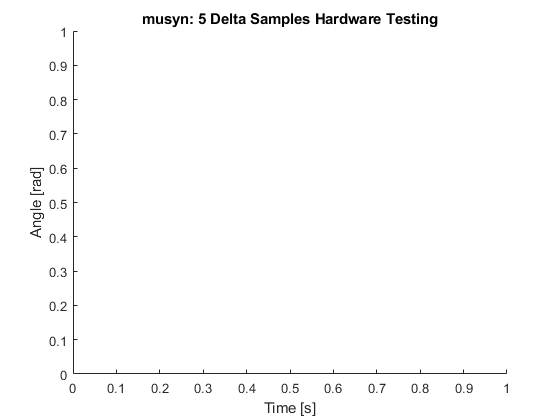

figure();
xlabel("Time [s]"); ylabel("Angle [rad]");
title("musyn: 5 Delta Samples Hardware Testing");

Delta_1 = usample(D_1, 1);
Delta_2 = usample(D_2, 1);

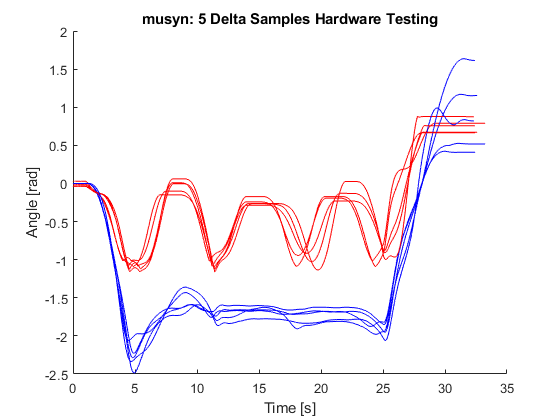

hold on;
plot(pitch_only.time, pitch_only.signals.values, 'r');
plot(yaw_only.time, yaw_only.signals.values, 'b');